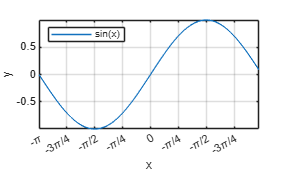

clear
close all

x = -pi:0.1:pi;
plot(x, sin(x))
xticks([-pi -3/4*pi, -pi/2 -pi/4  0 pi/4 pi/2 3/4*pi pi])
xticklabels({'-\pi', '-3\pi/4', '-\pi/2', '-\pi/4', '0', '-\pi/4', '-\pi/2', '-3\pi/4', '\pi'})
grid on
axis tight
legend('sin(x)', 'Location', 'northwest')
xlabel('x')
ylabel('y')

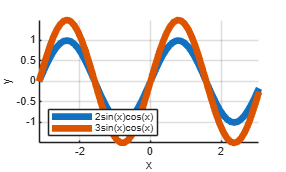

close all

hold on
plot(x, 2*sin(x).*cos(x), 'LineWidth', 5)
plot(x, 3*sin(x).*cos(x), 'LineWidth', 5)
grid on
axis tight
legend('2sin(x)cos(x)', '3sin(x)cos(x)', 'Location','southwest')
xlabel('x')
ylabel('y')

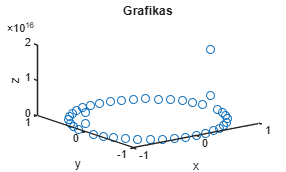

close all

t = 0:pi/20:4*pi;
x = sin(t);
y = cos(t);
z = tan(t);

plot3(x, y, z, 'o');
xlabel('x');
ylabel('y');
zlabel('z');
title('Grafikas')

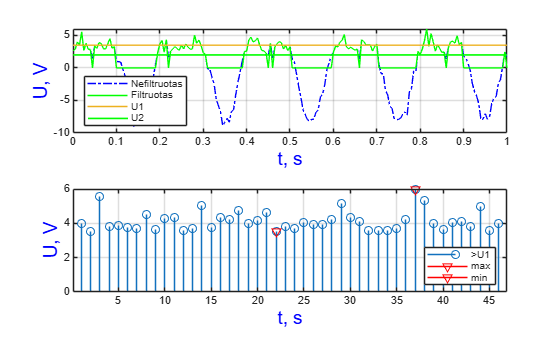

close all
clear
t = 0:0.005:1;
A = 5.5;
f = 5;
sigma = 0.8;
U_1 = 3.5;
U_2 = 2;
s = A*sin(2*pi*f*t)+0.5*A*cos(4*pi*f*t);
n = sigma*randn(size(t));
signalas_galutinis = s+n;
%a
a = signalas_galutinis([signalas_galutinis>U_1]);
%b
b = signalas_galutinis;
b([b<U_2]) = 0;
%c
size(signalas_galutinis);
%d
size(a);
%e
min(b);
max(b);

subplot(2, 1, 1)
plot(t, signalas_galutinis, '-.b');
hold on
plot(t, b, 'g')
plot([0 1], [3.5 3.5])
plot([0 1], [2 2], 'g', 'LineWidth', 1.25)
grid on
xlabel('t, s', 'Color', 'b', 'FontSize', 14)
ylabel('U, V',  'Color', 'b', 'FontSize', 14)
legend('Nefiltruotas', 'Filtruotas', 'U1', 'U2', 'Location','southwest')

subplot(2, 1, 2)
stem(a)
grid on
xlabel('t, s',  'Color', 'b', 'FontSize', 14)
ylabel('U, V',  'Color', 'b', 'FontSize', 14)
hold on
[max_value, max_index] = max(a);
plot(max_index, max_value, 'Marker', 'v', 'Color', 'r')
[min_value, min_index] = min(a);
plot(min_index, min_value, 'Marker', 'v', 'Color', 'r')
legend('>U1', 'max', 'min', 'Location','southeast')